## Declare Variables

% Constant variables
altitude = 25000; % Desired altitude of 25000 m
payloadMass = 500; % Desired payload mass of 500 kg
FS = [1:.5:3]'; % Self-selected number in range 1.5:2.5
Pgage = 10; % Gage pressure in Pa
gravity = 9.81; % Acceleration of gravity in m / s^2

% Variable variables (o_o )
    % Measurements based on information found in:
    % http://www.matweb.com/search/datasheet_print.aspx?matguid=bcd1ad1e1a7445aca5321d26f00bdf12
materialThickness = 3.81 * 10^-5; % Balloon material thickness in m
YS = 15.5 * 10^6; % Yield strength of balloon material in Pa
materialDensity = 924; % Density of material in kg / m^3
gasConstHe = 2.0769; % Gas constant for Helium in kJ / kg*K

## Declare equations

% Calculate sphere volume given radius
sphereVol = @(r) (4/3) * pi * (r.^3)

sphereVol = function_handle with value:
    @(r)(4/3)*pi*(r.^3)


% Calculate yield strength given factor of safety, gage pressure, radius,
% and thickness
yieldStrength = @(F_S, Pgage, r, t) (F_S .* (Pgage * r)) ./ (2 * t)

yieldStrength = function_handle with value:
    @(F_S,Pgage,r,t)(F_S.*(Pgage*r))./(2*t)


% Calculate stress given gage pressure, radius, and thickness
stress = @(Pgage, r, t) (Pgage * r) / (2 * t)

stress = function_handle with value:
    @(Pgage,r,t)(Pgage*r)/(2*t)


% Calculate radius given yield strength, factor of safety, gage pressure,
% and thickness
radius = @(YS, F_S, Pgage, t) (YS * (2 * t)) ./ (F_S .* Pgage)

radius = function_handle with value:
    @(YS,F_S,Pgage,t)(YS*(2*t))./(F_S.*Pgage)


% Calculate buoyancy force given fluid density, gravity, and volume
% THIS IS LIKELY INCORRECT --> MUST FIX THIS
buoyancy = @(density, volume) density * gravity * volume

buoyancy = function_handle with value:
    @(density,volume)density*gravity*volume


% Calculate force of gravity given mass
weight = @(mass) mass * gravity

weight = function_handle with value:
    @(mass)mass*gravity

## Calculate approximate balloon radius

bisonTopSpeed = 35 * 0.44704 % m/s

bisonTopSpeed = 15.6464

## Begin calculations

% Find atmospheric conditions based on 1976 model
[temp, speedSound, pressure, densityAir] = atmoscoesa(altitude)

temp = 221.6500

speedSound = 298.4551

pressure = 2.5110e+03

densityAir = 0.0395


% Find radius of balloon 
balloonRadius = radius(YS, FS, Pgage, materialThickness) % Radius in m

balloonRadius =   118.1100
   78.7400
   59.0550
   47.2440
   39.3700



% Find volume of balloon
balloonVolume = sphereVol(balloonRadius) % Volume in m^3

balloonVolume = 	1.0e+06 *

    6.9016
    2.0449
    0.8627
    0.4417
    0.2556



% Find buoyancy force
forceBuoyancy = buoyancy(densityAir, balloonVolume) % Buoyancy force in N

forceBuoyancy = 	1.0e+06 *

    2.6720
    0.7917
    0.3340
    0.1710
    0.0990



% Find force of gravity (weight of balloon)
amtBalloonMaterial = balloonVolume - sphereVol(balloonRadius - materialThickness)

amtBalloonMaterial =     6.6789
    2.9684
    1.6697
    1.0686
    0.7421


massHe = ((pressure .* balloonVolume) ./ (gasConstHe * temp)) ./ 1000 % Mass of He in kg

massHe = 	1.0e+04 *

    3.7646
    1.1154
    0.4706
    0.2409
    0.1394


totalMass = (amtBalloonMaterial * materialDensity) + payloadMass + massHe

totalMass = 	1.0e+04 *

    4.4317
    1.4397
    0.6749
    0.3897
    0.2580


forceGravity = weight(totalMass)

forceGravity = 	1.0e+05 *

    4.3475
    1.4124
    0.6620
    0.3823
    0.2531



% Need to find:
%     Mass of gas
%     cost of materials
%     amount of ballast
%     total stress on balloon

## Graphs of features vs Factor of Safety

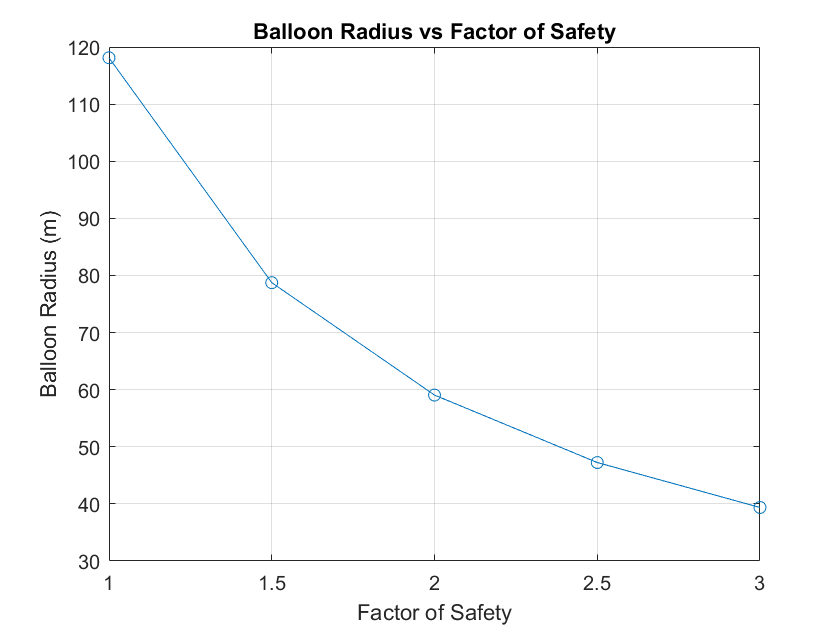

plot(FS, balloonRadius, 'o-')
grid on
title("Balloon Radius vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Balloon Radius (m)")

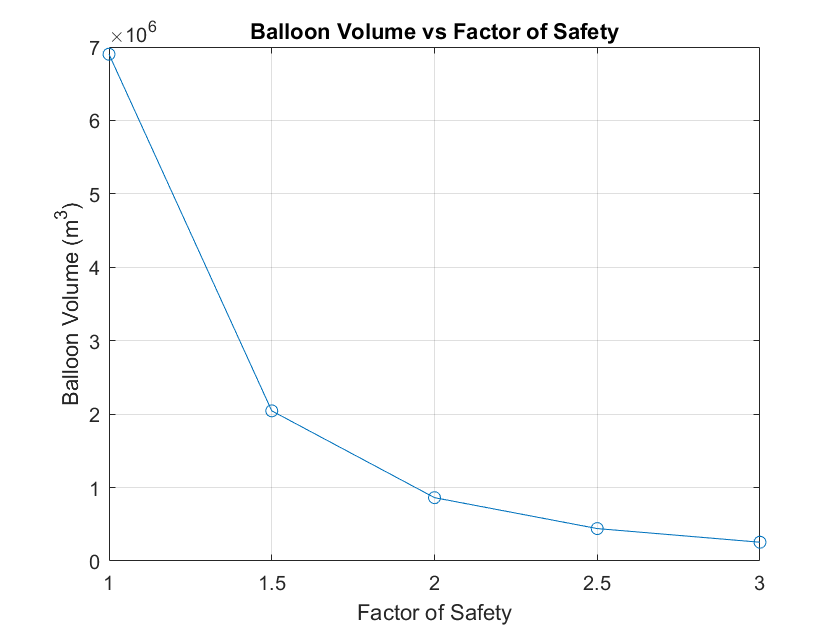


plot(FS, balloonVolume, 'o-')
grid on
title("Balloon Volume vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Balloon Volume (m^3)")

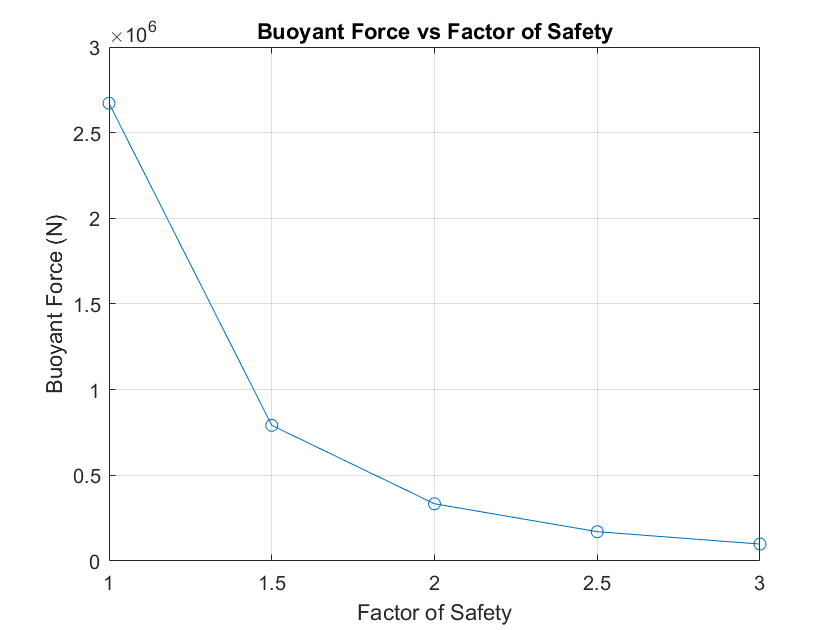


plot(FS, forceBuoyancy, 'o-')
grid on
title("Buoyant Force vs Factor of Safety")
xlabel("Factor of Safety")
ylabel("Buoyant Force (N)")